# Short Project 2

## Carlos Bergillos, Xavier Martín

### 1. Pose estimated

This function computes the pose integration of the robot.

The function receives the distance travelled by the left and right wheels (`L`, `R`) as an input, as well as the last pose of the robot (`x_ini`, `y_ini`, `theta_ini`), and returns the pose estimation for the next instant (`x`, `y`, `theta`).

To obtain the different values for L and R, we are using columns 6 and 7 of the `data_enc` Workspace variable.

By calling this function many times sequentially (with all the available values for `L` and `R`), we can obtain an aproximate trajectory of the robot.

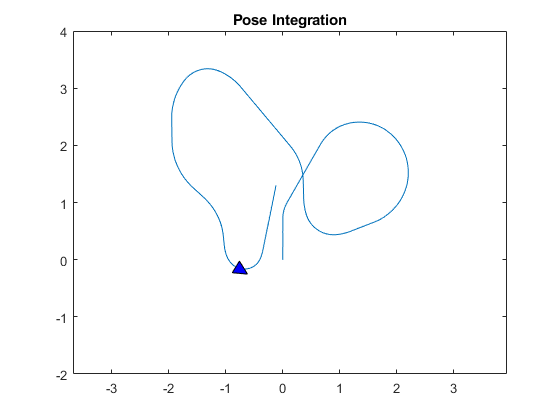

clear all
load('Work_Space_Localization_Short_project.mat')
time = 400;
steps = length(data_enc(:,1));
Robot = [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]';

xs(1) = 0;
ys(1) = 0;
thetas(1) = pi/2;

for index=2:steps
    L = (data_enc(index, 6)-data_enc(index-1, 6))/1000;
    R = (data_enc(index, 7)-data_enc(index-1, 7))/1000;
    
    [x, y, theta] = pose_integration_ins(xs(index-1), ys(index-1), thetas(index-1), L, R, width);
    
    xs(index) = x;
    ys(index) = y;
    thetas(index) = theta;
end
plot(xs, ys), title("Pose Integration");
Robot_tr=transl(xs(1,time),ys(1,time),0)*trotz(mod(thetas(1,time),2*pi))*trscale(0.6)*Robot;% moving the robot
patch(Robot_tr(1,:), Robot_tr(2,:),'b');
axis([-3 3 -2 4]);
axis equal;

The function is also introducing an error to the pose integration (matrix variable `V`). To account for this error, we will also plot the the covariance error ellipses:

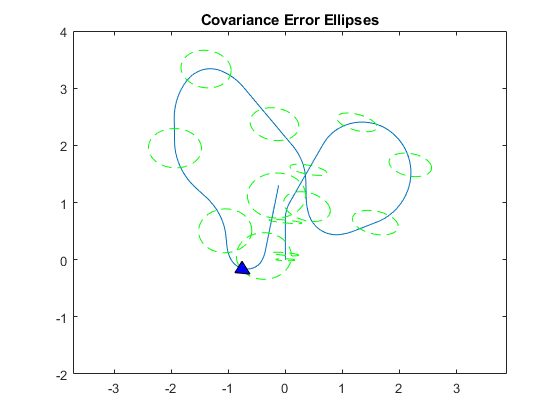

figure, plot(xs, ys), title("Covariance Error Ellipses");
for index=1:steps-64
    if (mod(index, 32) == 0)
            plot_ellipse(pk.signals.values(1:2,1:2,index),[xs(index), ys(index)],'--g'); % Plotting the covariance matrix 
    end
end
patch(Robot_tr(1,:), Robot_tr(2,:),'b');
axis([-3 3 -2 4]);
axis equal;

### 2. Polar to cartesian

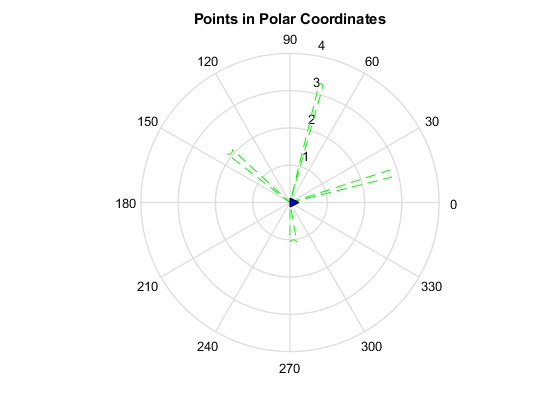

lm_polar = lds_dis(time,:)./1000;
[lm_cart_x lm_cart_y] = polar2cartesian_ins(lm_polar);
lm_rob_x = lm_cart_x;
lm_rob_y = lm_cart_y;
t = 0: 2*pi/359 : 2*pi;
figure, polar(t, lm_polar(1,2:361), '--g'); % Ploting the laser data wrt Robot frame
Robot_tr=trotz(0)*trscale(0.6)*Robot;% moving the robot
patch(Robot_tr(1,:), Robot_tr(2,:),'b');
title("Points in Polar Coordinates");

Next, this function takes the points provided by the laser of the robot (as found in the `lds_dis` Workspace variable) and outputs the cartesian coordinates of the points (`x`, `y`) in robot frame. 

To do this, for each of the 360 columns of the input, corresponding to the readings of 360 degrees, we obtain the cartesian coordinates by multiplying the given distance by the *sin* and *cos* of the laser angle, to obtain *x* and *y* in robot frame.

### 3. Robot to world

Now, we want to transform the points from robot frame to world frame. Thanks to the pose integration we did in section 1, we have the *x* and *y* position of the robot, as well as its angle *theta*.

The function takes the laser points in robot frame (*data_x*, *data_y*) and the robot's pose (*x_ini*, *y_ini*, *theta_ini*), and outputs the points in world frame (*xs*, *ys*).

We just need to apply a transformation to the points, with transl(*x_ini*, *y_ini*) and trotz(*theta_ini*).

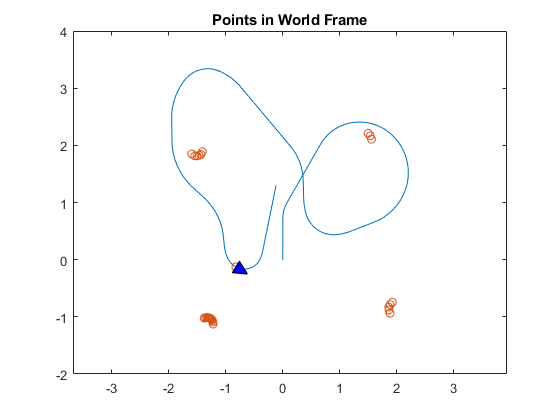

[lm_world_x lm_world_y] = robot2world_ins(lm_rob_x, lm_rob_y, xs(time), ys(time), thetas(time));
figure, plot(xs, ys), title("Points in World Frame");
hold on;
scatter(lm_world_x(:), lm_world_y(:));
Robot_tr=transl(xs(1,time),ys(1,time),0)*trotz(mod(thetas(1,time),2*pi))*trscale(0.6)*Robot;% moving the robot
patch(Robot_tr(1,:), Robot_tr(2,:),'b');
axis([-3 3 -2 4]);
axis equal;
hold off;

### 4. Associated Land Mark

In this section we have calculated the points (in World Space) where the robot thinks the Land Marks are.

To do so, we have created a new function (nearest_to) which has the following inputs: X and Y coordinates of the real Land Marks (`LM_X`, `LM_y`), X and Y coordinates of the computed Land Marks by the robot in world space (*data_X*, *data_Y*), the number of points we will take into account to compute the center of a Land Mark (`n`) and the maximum distance in meters a point can be from a Land Mark (`thr`). 

This function returns the X and Y coordinates in world space where the robot is detecting the Land Marks.

Due to the noise we have included (simulating that the floor is not completely even) and other errors, the pose integration does not provide the real location of he robot. As a consequence, the calculated Land Marks are moved a bit, and are not in the same place than the real Land Marks. If there are no points around a Land Mark, the robot will have any information about where that Land Mark is. This is because the value of our threshold of maximum distance (last input parameter). 

We compute the average (center of gravity) of the nearest points to a given Land Mark to obtain the new position of that LandMark.

In this section we have used the given information about the real Land Marks (`LandMark` variable in the Workspace). 

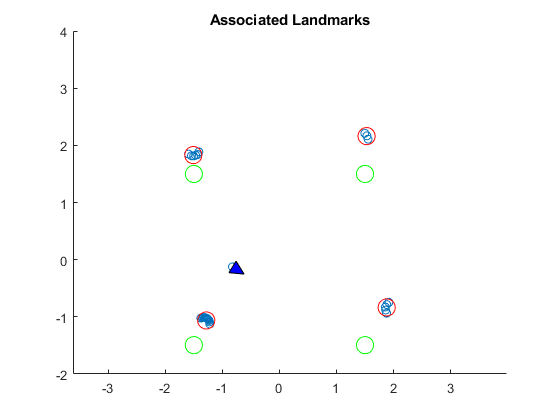

figure, scatter(lm_world_x(:), lm_world_y(:));
hold on;
Robot_tr=transl(xs(1,time),ys(1,time),0)*trotz(mod(thetas(1,time),2*pi))*trscale(0.6)*Robot;% moving the robot
patch(Robot_tr(1,:), Robot_tr(2,:),'b');
CalculatedLandMarks = [];
for i=1:length(LandMark)
    circle (LandMark(i,:)',0.15, 'color', 'g');
    [l_x l_y] = nearest_to(LandMark(i, 1), LandMark(i, 2), lm_world_x(:), lm_world_y(:), 5, 1);
    if (~isnan(l_x) && ~isnan(l_y))
        CalculatedLandMarks = [CalculatedLandMarks; l_x l_y];
        circle ([l_x l_y], 0.15, 'color', 'r');
    end
end
title("Associated Landmarks")
axis([-3 3 -2 4]);
axis equal;
hold off;

In the previous image, we can see the real Land Marks in green (which do not move) and the Land Marks that the robot has detected in red.

### 5. Similarity Transform

Next, we correct the robot's pose integration and trajectory with the information provided by the laser. To do so, every X steps (64 approx. in our case) we compute the error in the pose of the robot (*X*, *Y* and *theta)*. Then, we apply a transformation to the pose integration to correct this error.

With this, the robot is again in the given trajectory and the predicted Land Marks are also in the same place as the real Land Marks. 

In this section we have used again the given information of the real Land Marks (`LandMark` variable in the workspace). 

The `similarity_transform` function computes this error. It takes as inputs the real Land Marks and the predicted Land Marks by the robot. This function computes two matrices: one with the real Land Marks (`A`) and the other with the predicted Land Marks by the robot (`B`). Then it applies a matrix operation: `inv((A'*A))*A'*B`. The result of this multiplication gives the *theta*, *X* and *Y* errors of the robot. Then if we apply these values to update the robot values we redirect the robot to a good trajectory.

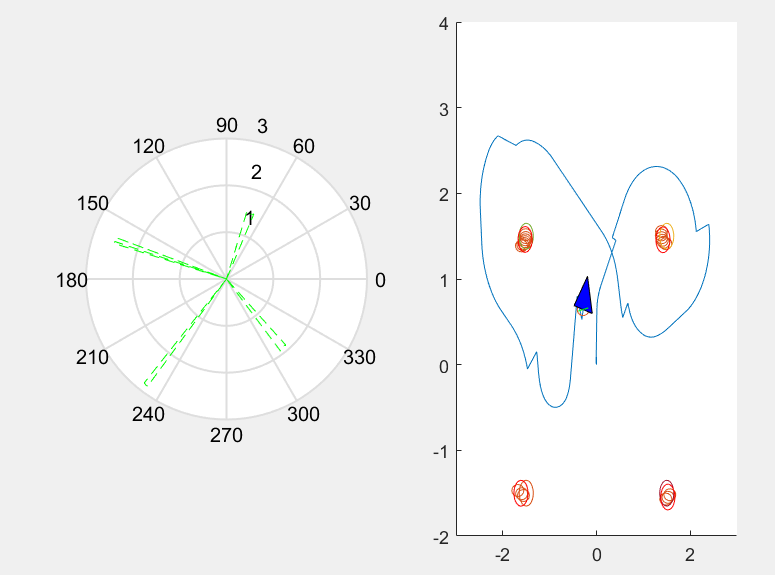

As we can see in this figure, the trajectory (blue line) changes every X steps due to the corrections done thanks to the `similarity_transform` function. We can also see how the real Land Marks and the perceived Land Marks overlap, as this image was taken right after one of these corrections.